clear; close all; clc
addpath('dep')

%% load a file
dataLoc = '~/Downloads/v4-7a';
load([dataLoc '/zippy_grid_2afc_240521-152353_dense.mat'])

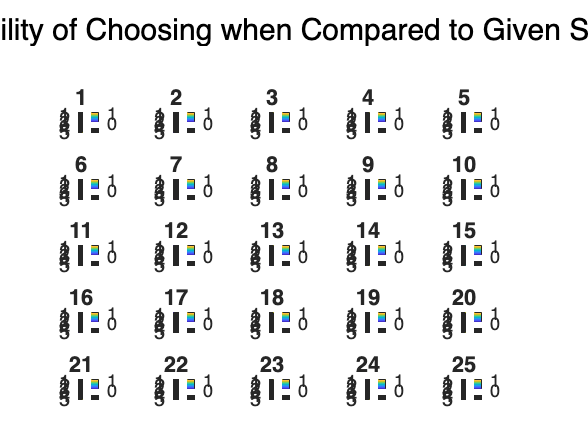

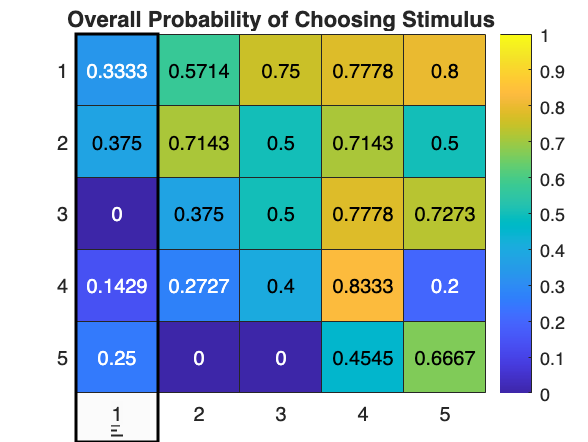

%plotPsychometric(params)


plotChoiceHM(params)

function plotChoiceHM(params)
    gen_HM = NaN(5);
    for stim = 1:25
        HM = NaN(5);
        overall_stim_choices = sum([params.stimRF_num] == stim & [params.selected] == 1); 
        overall_stims = sum([params.stimRF_num] == stim);
        gen_HM(stim) = overall_stim_choices/overall_stims;
        for i = 1:25
            if i ~= stim
                tot_trials = sum([params.stimRF_num] == stim & [params.stimOpp_num] == i);
                tot_choices = sum([params.stimRF_num] == stim & [params.stimOpp_num] == i & [params.selected] == 2);
                HM(i) = tot_choices/tot_trials; 
            end
        end
        subplot(5, 5, stim)
        HM = HM.';
        heatmap(HM, 'ColorLimits', [0, 1], 'ColorMap', parula)
        title(stim)
    end
    sgtitle("Probability of Choosing when Compared to Given Stimulus")

    figure;
    gen_HM = gen_HM.';
    heatmap(gen_HM, 'ColorLimits', [0, 1], 'ColorMap', parula)
    title("Overall Probability of Choosing Stimulus")
end

function plotPsychometric(params)
    colorTrials = (mod([params.stimRF_num],5)-mod([params.stimOpp_num],5)) == 0;
    shapeTrials = (ceil([params.stimRF_num]/10) - ceil([params.stimOpp_num]/10)) == 0;
    diagTrials = [5 9 13 17 21];
    mixedTrials = ~shapeTrials & ~colorTrials;
    
    stimVals = [mat2vec(repmat(1:5,5,1)) mat2vec(repmat(5:-1:1,1,5))];
    colIds_1 = stimVals([params.stimRF_num],1);
    colIds_2 = stimVals([params.stimOpp_num],1);
    
    shpIds_1 = stimVals([params.stimRF_num],2);
    shpIds_2 = stimVals([params.stimOpp_num],2);
    choices = [params.selected]';
    
    clf; hold on;
    
    diff_col = colIds_1(colorTrials)-colIds_2(colorTrials);
    xx = unique(diff_col);
    mm = groupsummary(choices(colorTrials),diff_col,'mean')-1;
    ss = groupsummary(choices(colorTrials),diff_col,'std')./sqrt(groupsummary(choices(colorTrials),diff_col,'nnz'));
    patch([xx;flipud(xx)],[mm-ss/2;flipud(mm+ss/2)],[0.9 0.5 0.2],'edgecolor','none','facealpha',0.5)
    plot(xx,mm,'-o','color',[0.9 0.5 0.2],'LineWidth',2,'MarkerFaceColor','w');
    
    diff_shp = shpIds_1(shapeTrials)-shpIds_2(shapeTrials);
    xx = unique(diff_shp);
    mm = groupsummary(choices(shapeTrials),diff_shp,'mean')-1;
    ss = groupsummary(choices(shapeTrials),diff_shp,'std')./sqrt(groupsummary(choices(shapeTrials),diff_shp,'nnz'));
    patch([xx;flipud(xx)],[mm-ss/2;flipud(mm+ss/2)],[0.2 0.5 0.9],'edgecolor','none','facealpha',0.5)
    plot(xx,mm,'-o','color',[0.2 0.5 0.9],'LineWidth',2,'MarkerFaceColor','w');


    %diff_diag = shpIds_1(diagTrials)-shpIds_2(diagTrials);
    %xx = unique(diff_diag);
    %mm = groupsummary(choices(diagTrials),diff_diag,'mean')-1;
    %ss = groupsummary(choices(diagTrials),diff_diag,'std')./sqrt(groupsummary(choices(diagTrials),diff_diag,'nnz'));
    %patch([xx;flipud(xx)],[mm-ss/2;flipud(mm+ss/2)],[0.2 0.7 0.2],'edgecolor','none','facealpha',0.5)
    %plot(xx,mm,'-o','color',[0.2 0.7 0.2],'LineWidth',2,'MarkerFaceColor','w');

    mix_diff_shp = shpIds_1(mixedTrials) - shpIds_2(mixedTrials);
    mix_diff_col = colIds_1(mixedTrials) - colIds_2(mixedTrials);
    diff_mix = (mix_diff_shp + mix_diff_col)/2;
    xx = unique(diff_mix);
    mm = groupsummary(choices(mixedTrials),diff_mix,'mean')-1;
    ss = groupsummary(choices(mixedTrials),diff_mix,'std')./sqrt(groupsummary(choices(mixedTrials),diff_mix,'nnz'));
    patch([xx;flipud(xx)],[mm-ss/2;flipud(mm+ss/2)],[0.2 0.7 0.2],'edgecolor','none','facealpha',0.5)
    plot(xx,mm,'-o','color',[0.2 0.7 0.2],'LineWidth',2,'MarkerFaceColor','w');
    
    fixPlot(gca,[-4.8 4.8],[-0.1 1.1],'stim difference','probability of saccde to RF',-4:4,0:0.25:1,'',{'' 'color' '' 'shape' '' 'mixed'})
end

